# Differential correction for Lyapunov orbits


global FORWARD tol mu
FORWARD = 1;
tol = 1e-8;

mu = 0.0121; % Earth-Moon

poly1 = [1  -1*(3-mu)  (3-2*mu)  -mu   2*mu  -mu ];

rt1 = roots(poly1)

rt1 =    1.4946 + 0.8613i
   1.4946 - 0.8613i
  -0.0761 + 0.1456i
  -0.0761 - 0.1456i
   0.1507 + 0.0000i


for k=1:5
    if isreal(rt1(k)) 
        gamma = rt1(k)
    end
end

gamma = 0.1507


xL = (1-mu)-gamma

xL = 0.8372


T = 2*pi ; % period of primaries in non-dimensional units

% L1 eigenbasis

mubar=mu/abs(xL-1+mu)^3 + (1-mu)/abs(xL+mu)^3;

a=1+2*mubar;
b=mubar -1 ;

lam = sqrt( 0.5*(mubar-2+sqrt(9*mubar^2-8*mubar)));
nu  = sqrt(-0.5*(mubar-2-sqrt(9*mubar^2-8*mubar)));

sigma =  2*lam/(lam^2 + b)

sigma = 0.4602

tau   =-(nu^2  + a)/(2*nu)

tau = -3.5859


u1 = [ 1 ; -sigma ;  lam ; -lam*sigma ] ;
u2 = [ 1 ;  sigma ; -lam ; -lam*sigma ] ;
u  = [ 1 ;    0   ;   0  ;   nu*tau   ] ;
v  = [ 0 ;   tau  ;  -nu ;     0      ] ;


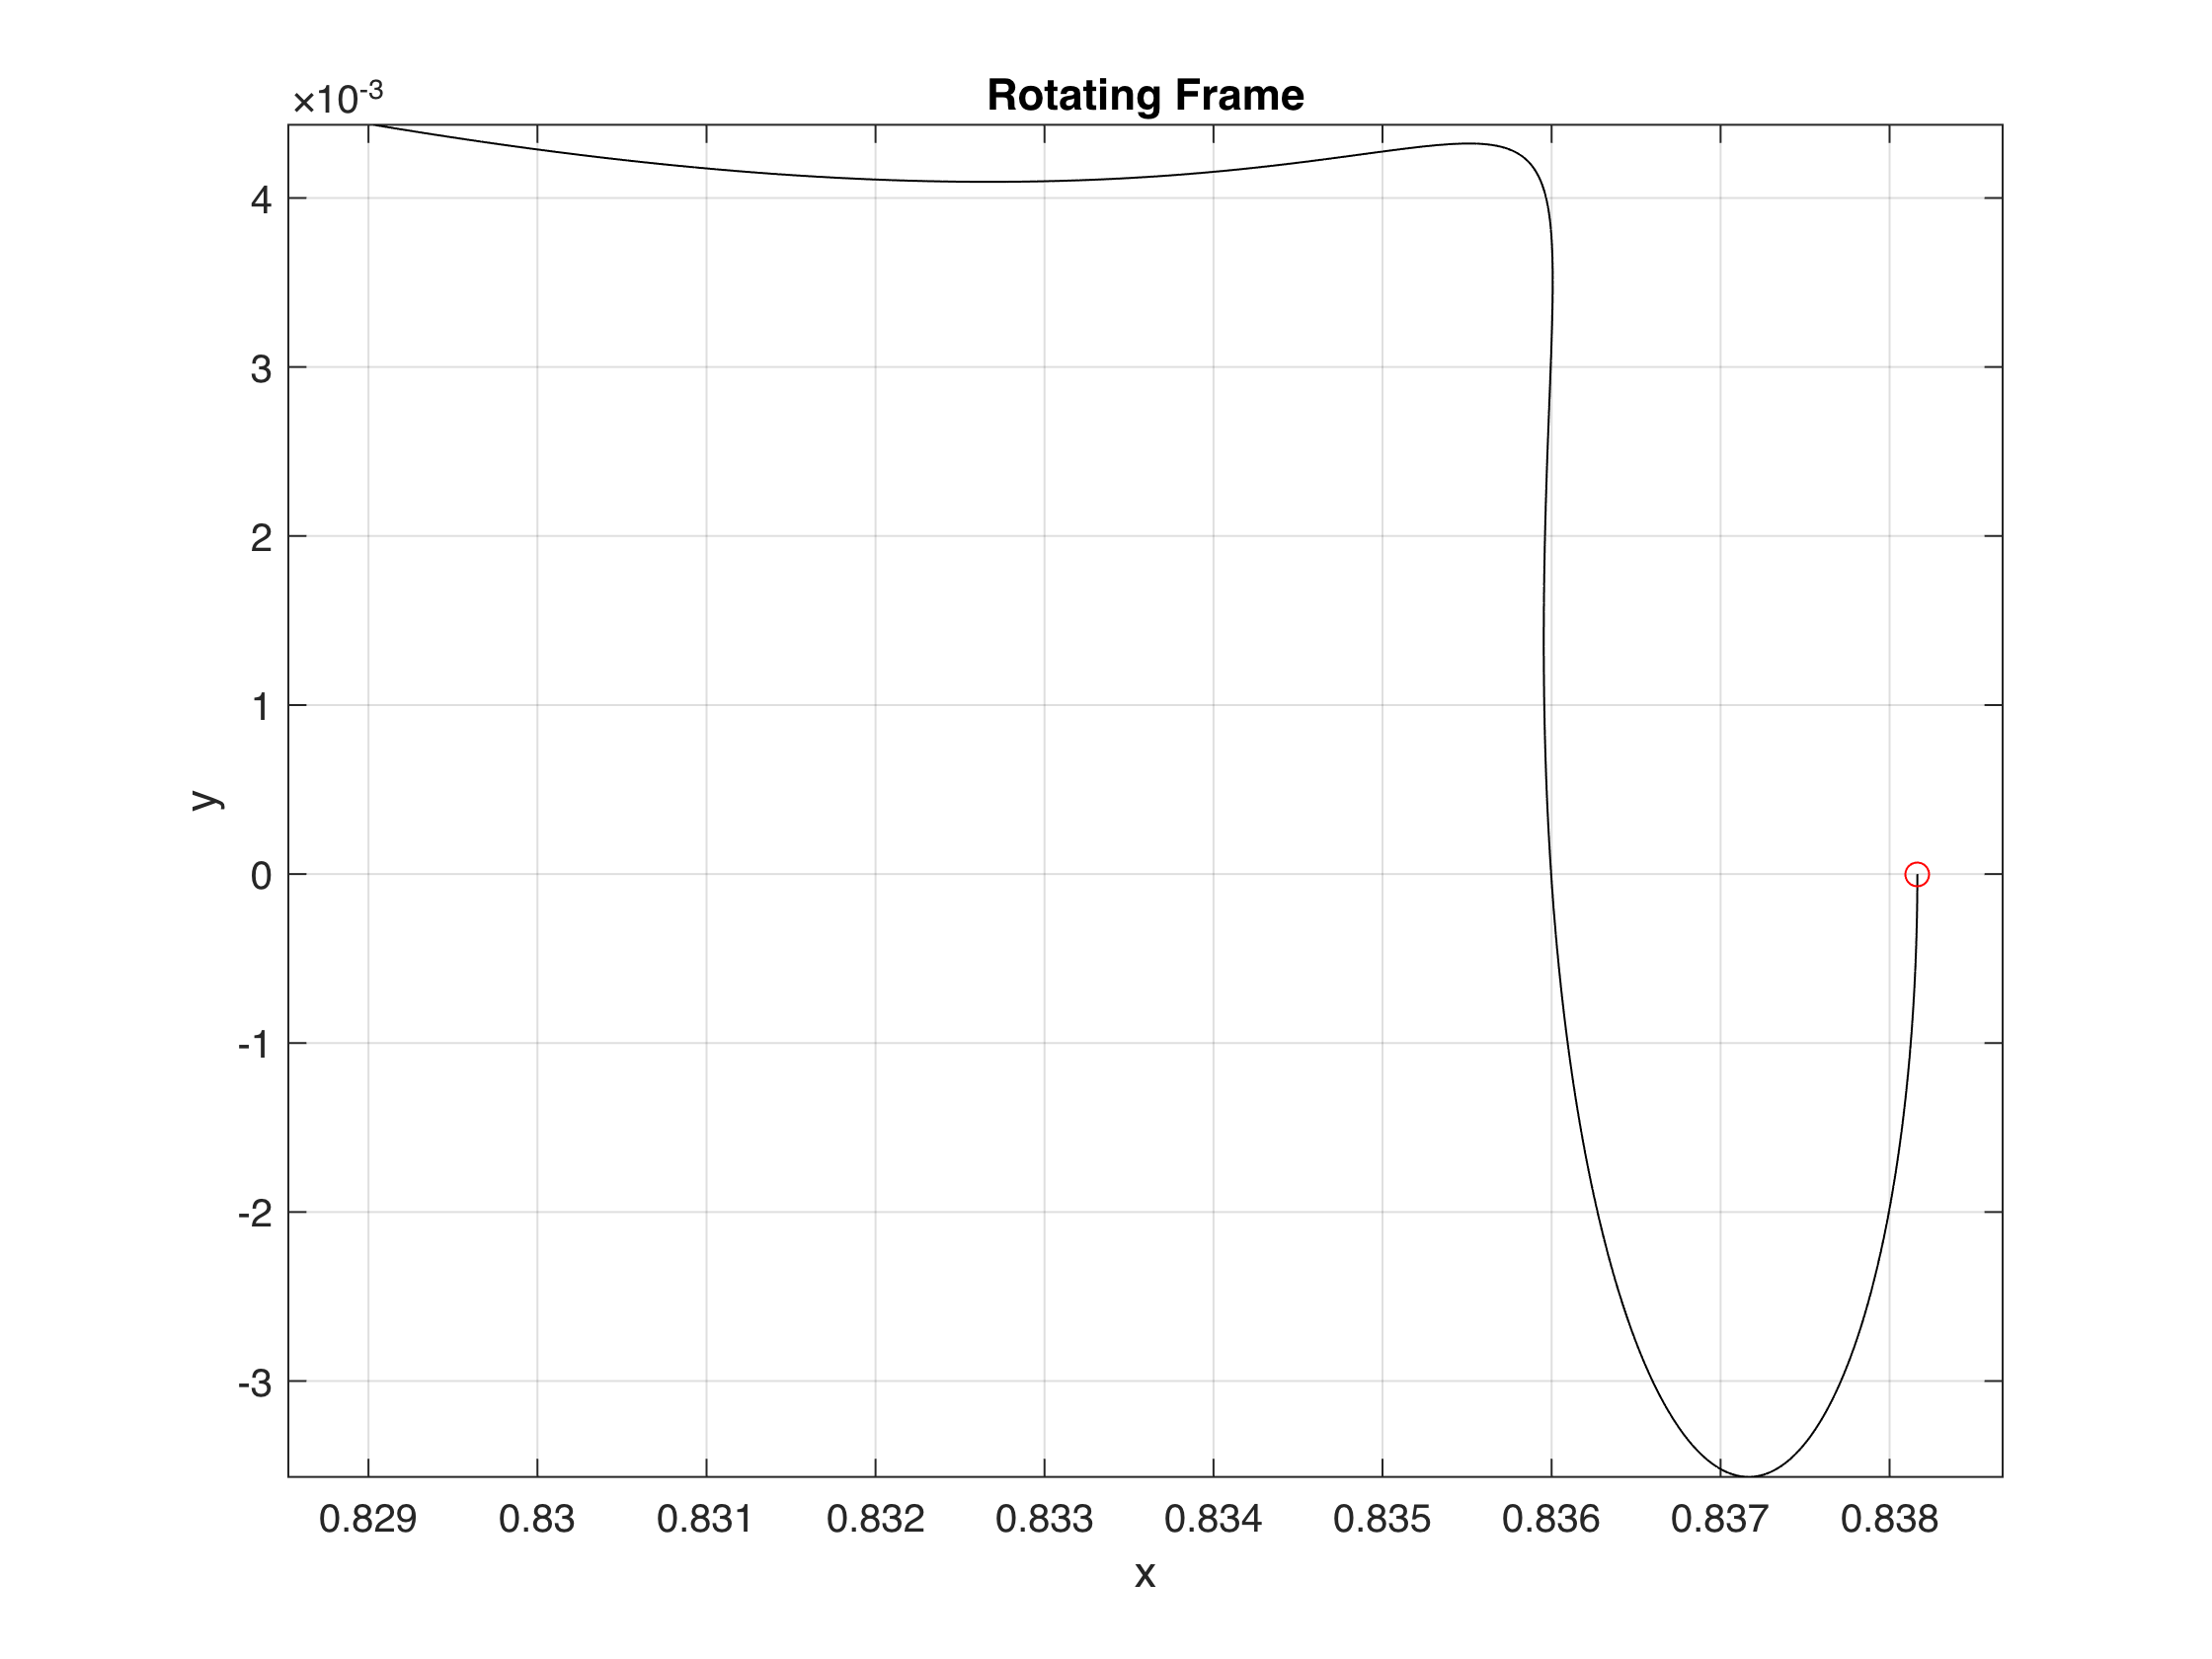

% Compute small periodic orbit (planar Lyapunov orbit)

tfinal = 2*pi/nu;

tspan = 0:0.001*T:tfinal;

XL = [ xL ; 0 ; 0 ; 0 ] ;

displacement = 1e-3; % nondimensional displacement from L
X0 = XL + displacement*u ; % initial condition

X0(4)=0.9985*X0(4);

opts = odeset('AbsTol',1e-8,'RelTol',1e-6);
[t,X] = ode45(@(t,X) prtbp(t,X), tspan, X0, opts) ;

x =X(:,1); 
y =X(:,2);

plot(x,y,'k',X0(1),X0(2),'ro');
title('Rotating Frame'); 
xlabel('x'); ylabel('y');
axis equal; grid on

x0g = X0;
%[t1,xx1]=find0(x0g);
[x0po,t1] = liadifcor(x0g);

attempt = 1

attempt = 2

attempt = 3

attempt = 4

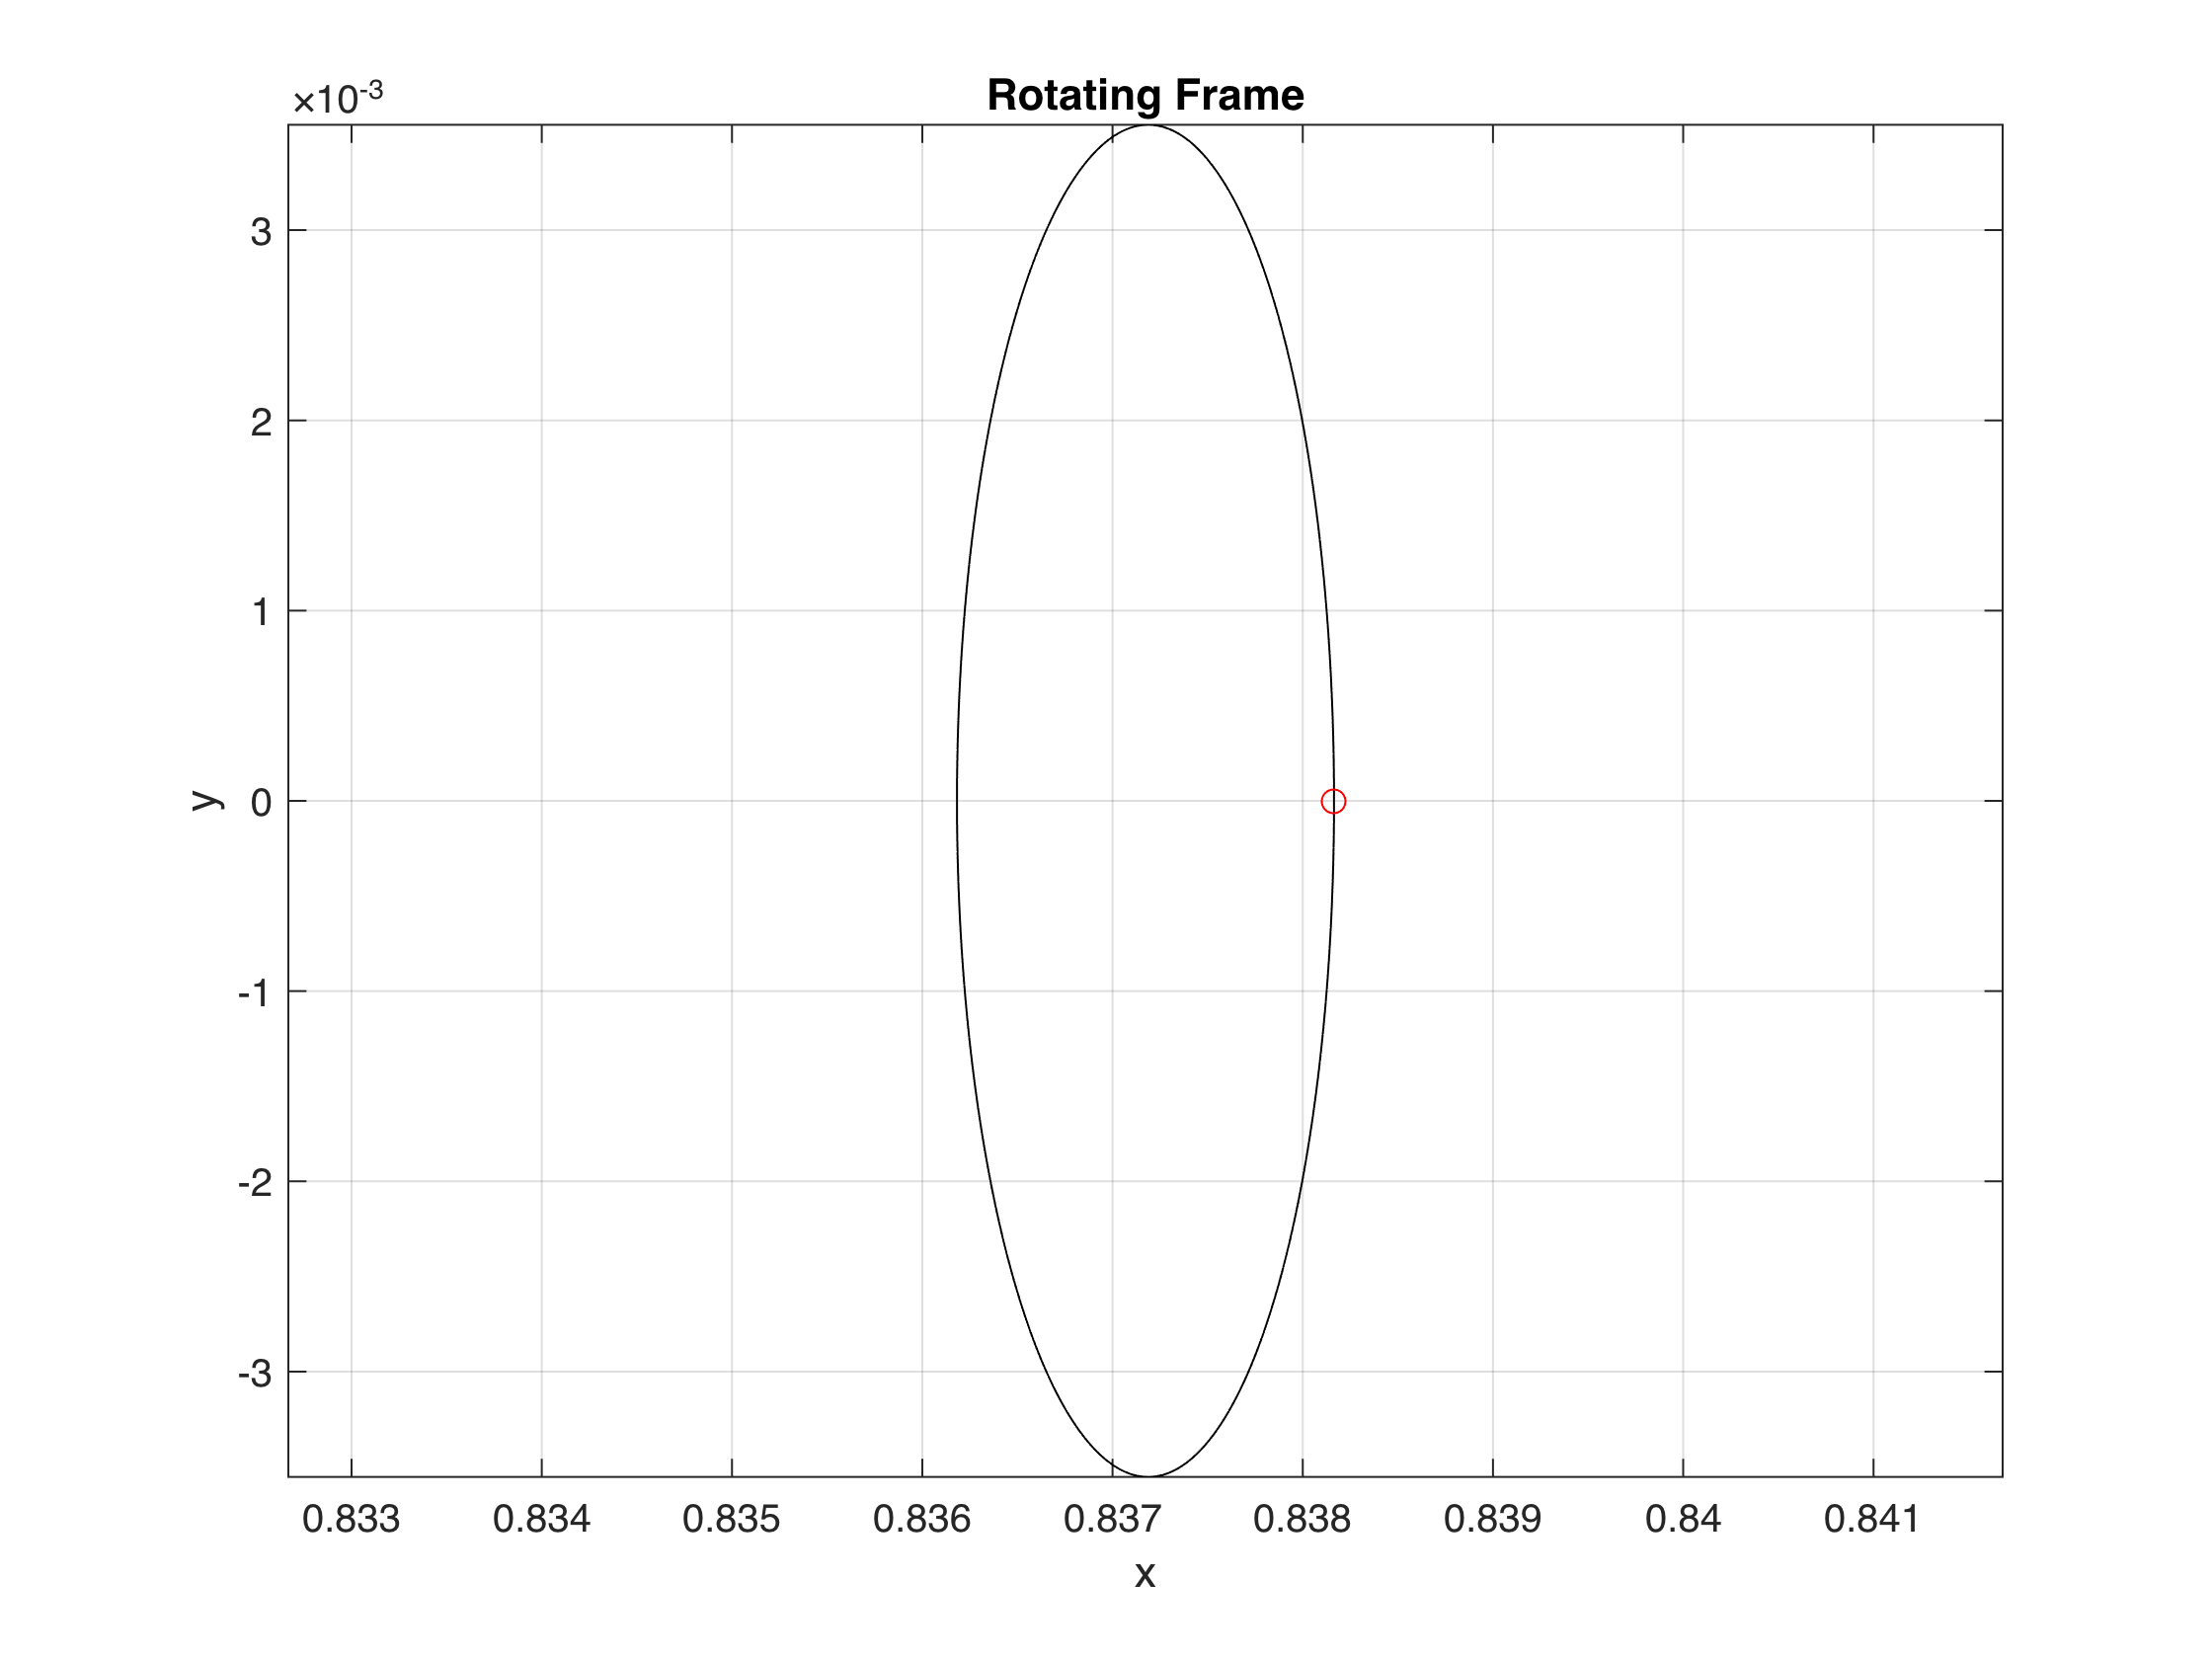

Tpo = 2*t1 ;

tspan = 0:0.001*Tpo:Tpo;

opts = odeset('AbsTol',1e-8,'RelTol',1e-6);
[t,X] = ode45(@(t,X) prtbp(t,X), tspan, x0po, opts) ;

x =X(:,1); 
y =X(:,2);

plot(x,y,'k',X0(1),X0(2),'ro');
title('Rotating Frame'); 
xlabel('x'); ylabel('y');
axis equal; grid on

X(end,:)' - x0po

ans = 	1.0e+-9 *

   -0.0480
    0.0209
   -0.1446
    0.0606



[x,t,phi_T,PHI]=PHIget(x0po,tfinal);
[V,D]=eigs(phi_T);

D(1,1)

ans = 2.6715e+03

D(2,2)

ans = 1.0000 + 0.0008i

D(3,3)

ans = 1.0000 - 0.0008i

D(4,4) 

ans = 3.7432e-04

1/D(1,1)

ans = 3.7432e-04


Tpo/(2*pi)

ans = 0.4285

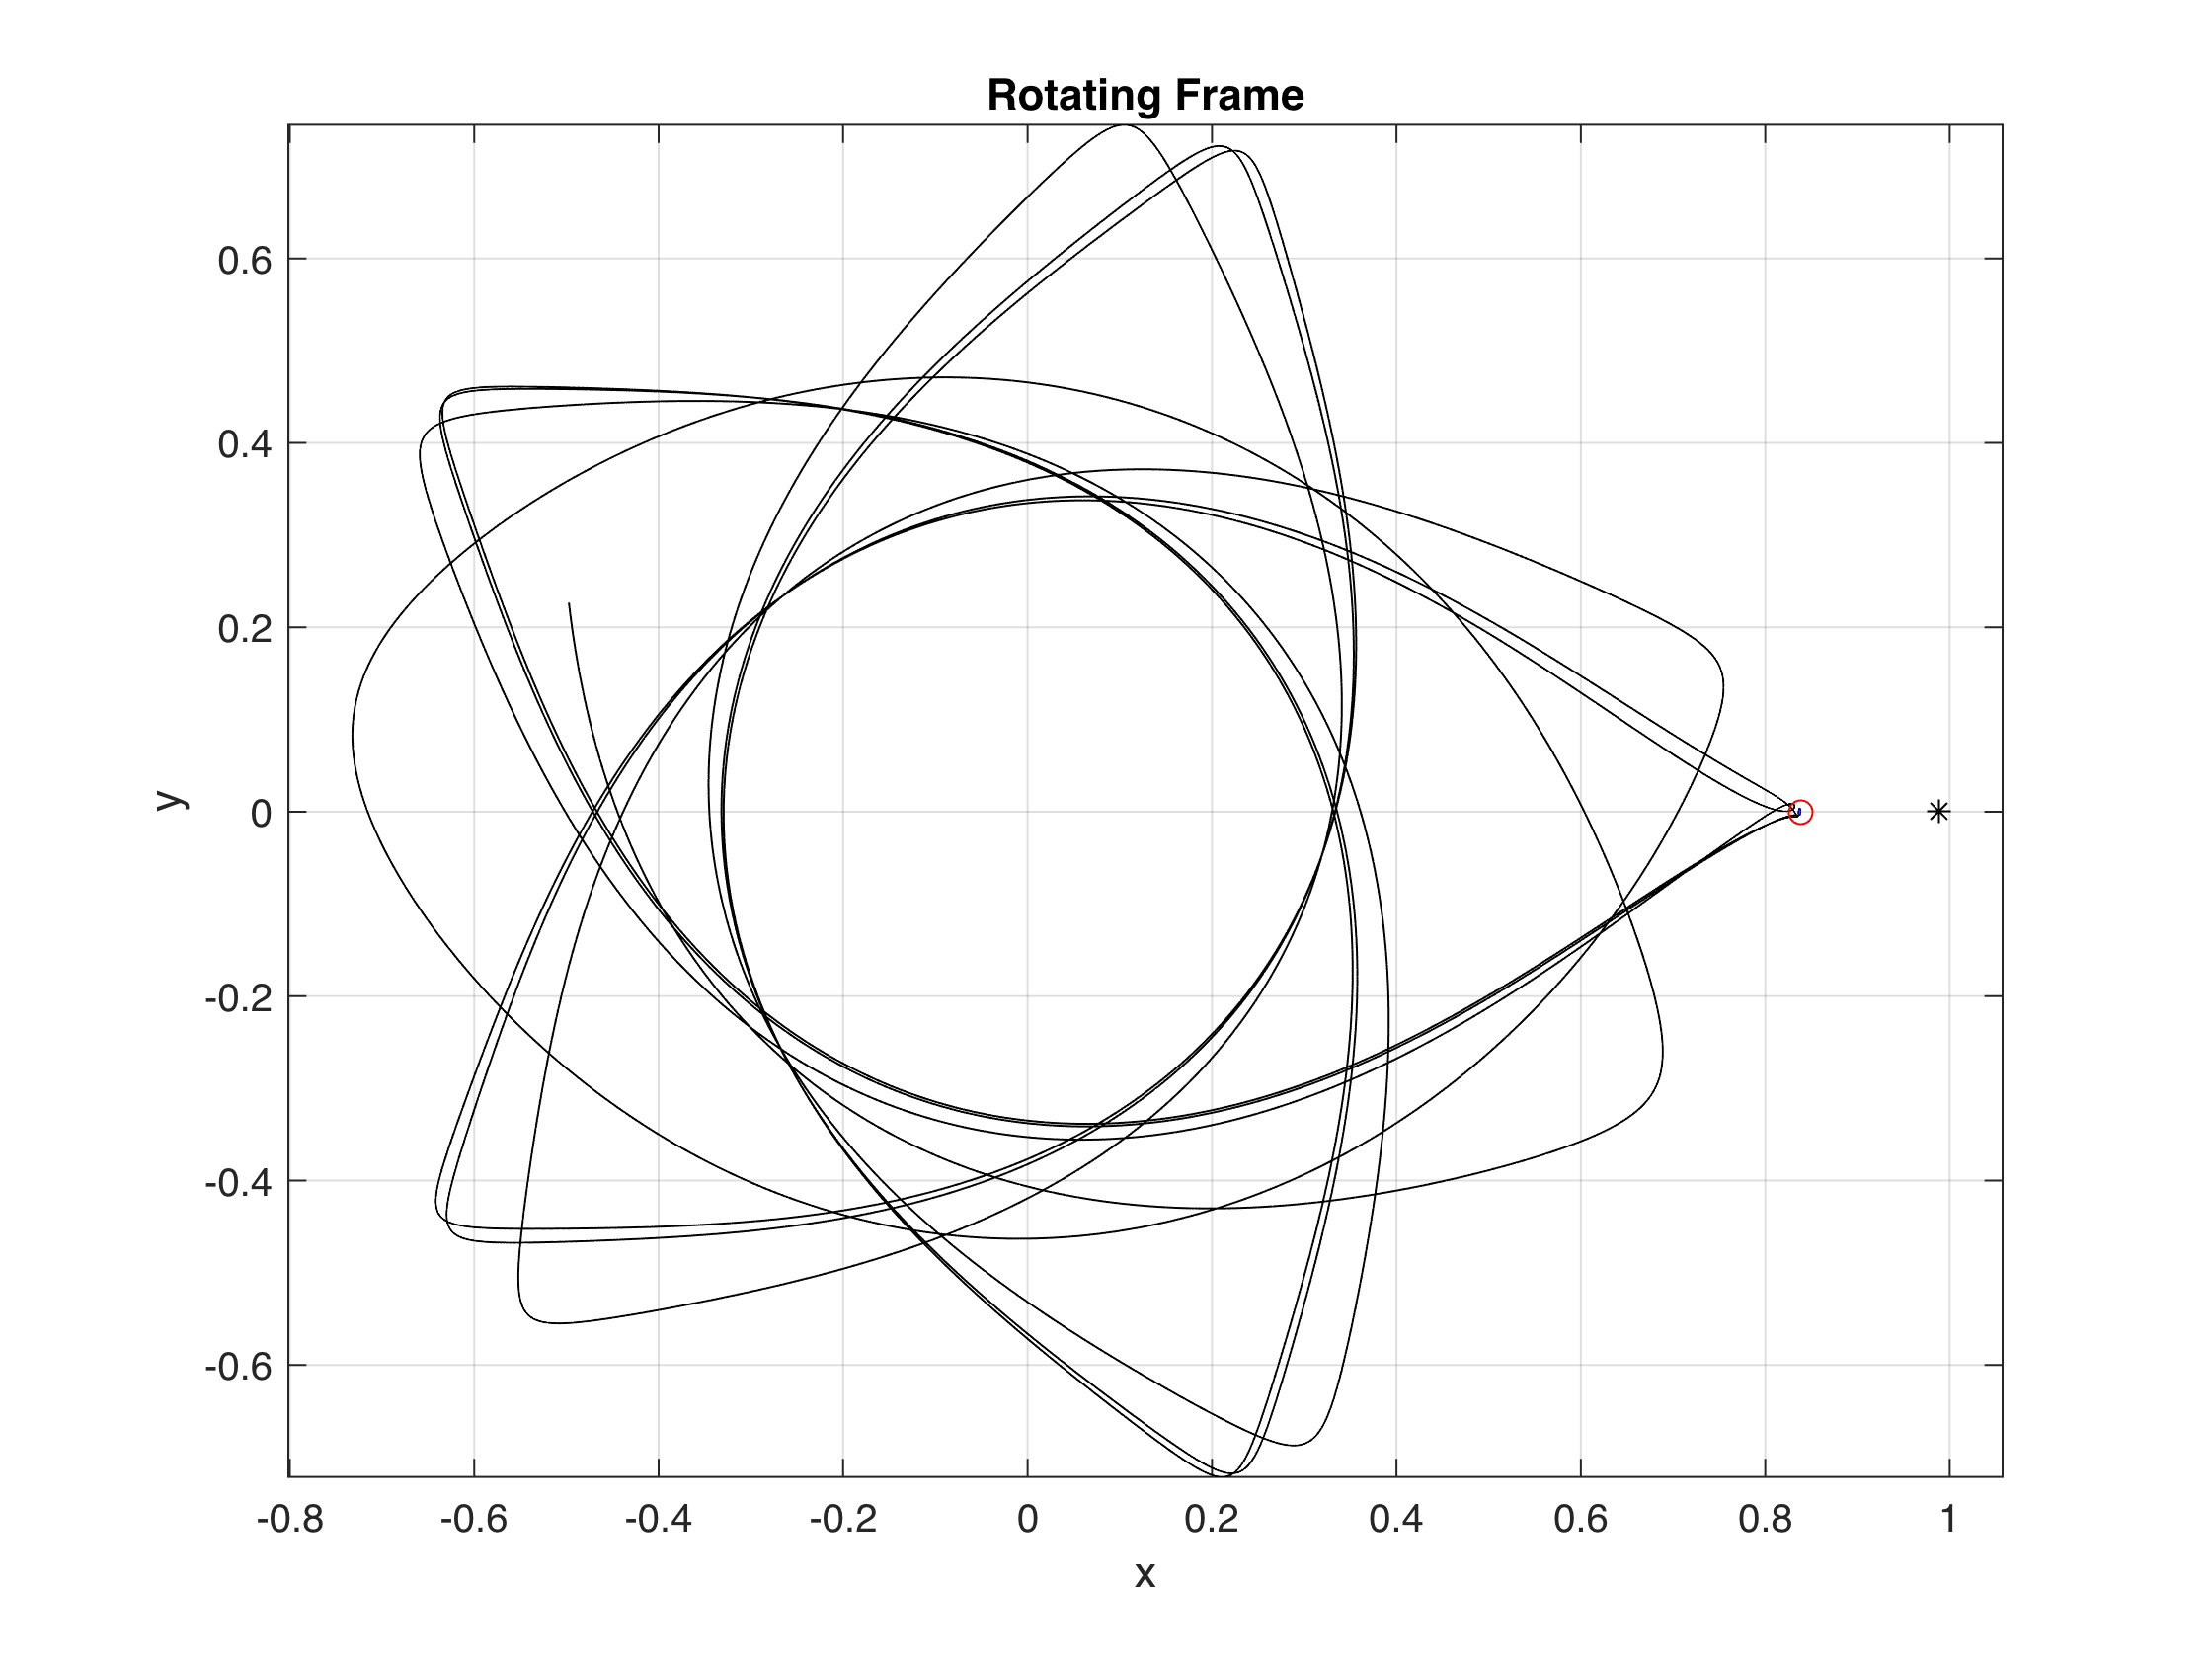


e_stable = V(:,4)/norm(V(:,4));
displacement = 1.e-5;

x0 = x0po + displacement*e_stable;

tspan = 0:-0.001*Tpo:-2*Tpo;

opts = odeset('AbsTol',1e-8,'RelTol',1e-6);
[t,X] = ode45(@(t,X) prtbp(t,X), tspan, x0, opts) ;
x =X(:,1); 
y =X(:,2);

plot(x,y,'k',x0(1),x0(2),'ro');
hold on

x0 = x0po + displacement*e_stable;

tspan = 0:0.001*Tpo:1*Tpo;
[t,X] = ode45(@(t,X) prtbp(t,X), tspan, x0, opts) ;
x =X(:,1); 
y =X(:,2);
plot(x,y,'b',1-mu,0,'k*');

title('Rotating Frame'); 
xlabel('x'); ylabel('y');
axis equal; grid on

function xdot = prtbp(t,x)
% xdot = prtbp(t,x)
%
% with the LARGER MASS, m1 to the left of the origin at (-mu,0)
% and m2, or the planet (ie. Earth), is at (1 - mu, 0)
%
%                L4
%
% -L3----m1--+-------L1--m2--L2-
%
%                L5
%
% Shane Ross (revised 9.23.97)
global mu

mu1=1-mu; % mass of larger  primary (nearest origin on left)
mu2=  mu; % mass of smaller primary (furthest from origin on right)

r3= ((x(1)+mu2)^2 + x(2)^2)^1.5;     % r: distance to m1, LARGER MASS
R3= ((x(1)-mu1)^2 + x(2)^2)^1.5;     % R: distance to m2, smaller mass

xdot    = zeros(4,1);
xdot(1) = x(3);
xdot(2) = x(4);
xdot(3) = x(1)-(mu1*(x(1)+mu2)/r3) -(mu2*(x(1)-mu1)/R3)+2*x(4);
xdot(4) = x(2)-(mu1* x(2)     /r3) -(mu2* x(2)     /R3)-2*x(3);
end


%% Compute 3-Body Energy

function E = energy(X,mu)

mu1=1-mu;mu2=mu;

Vsqrd= X(:,3).^2+X(:,4).^2 ;
Ubar = - mu1./sqrt((X(:,1)+mu2).^2+X(:,2).^2) ...
       - mu2./sqrt((X(:,1)-mu1).^2+X(:,2).^2) ...
       - 0.5*(X(:,1).^2+X(:,2).^2) - 0.5*mu1*mu2 ;

E = 0.5*Vsqrd + Ubar ;

end


function Xin = rot2iner(X,t,M,mu,del)
% Xin=rot2iner(X,T,M,mu,del);
%
% Transformation from M body-centered rotating (nondim.) coordinates to
% inertial (nondim.) coordinates
%
% M = 2 : smaller mass(M2) centered inertial coordinates
% M = 1 : LARGER  mass(M1) centered inertial coordinates
% M = 0 : center-of-mass   centered inertial coordinates
%
% X   = state 4- or 6-vector matrix (in nondim. rotating coordinates)
% t   = nondimensional CR3BP time
% del = the rotation offset at time t=0 (in radians)
%
% Xrot = inv(B)*(Xin - A)
% see p.6 of Cassall(1996)
%
% NOTE: nondim. means nondimensional CR3BP units where 
%	sum of primaries' mass = 1
%	constant distance between primaries = 1
%	period of primaries' orbit = 2*pi
% 
%-----------------------------------------------------------------------
% CR3BP (Circular Restricted Three-Body [Gravitational] Problem)
% with the LARGER MASS, M1 to the left of the origin at (-mu,0)
% and the smaller mass, M2, or the planet (ie. Earth), is at (1 - mu, 0)
%
%       (rotating coords)
%
%                 L4
% -L3------M1--+-----L1--M2--L2-
%                 L5
%
% Shane Ross (revised 7.15.97)
%

% Defaults
if nargin<=4
    del=0;
    if nargin<=3
        mu=0;
        if nargin<=2
            M=0;
        end
    end
end

if     M==1, d= -mu; 	% distance to LARGER  primary in CR3BP (M1)
elseif M==2, d=1-mu;	% distance to smaller primary in CR3BP (M2)
elseif M==0, d=0;	    % center-of-mass is the origin
end

c=cos(t + del); s=sin(t + del);

Xin=[];
Xin(:,1)= c.*(X(:,1)-d) - s.*X(:,2);
Xin(:,2)= s.*(X(:,1)-d) + c.*X(:,2);
Xin(:,3)=-s.*(X(:,1)+X(:,4)-d) + c.*(X(:,3) - X(:,2));
Xin(:,4)= c.*(X(:,1)+X(:,4)-d) + s.*(X(:,3) - X(:,2));

end


%% Differential Correction function

function [x0,t1] = liadifcor(x0g,show)
% [x0,t1]=liadifcor(x0g,show)
%
% This is the differential correction routine to create planar periodic 
% Liapunov orbits about L1,L2, or L3 in the CR3BP. It keeps the initial 
% x value constant and varies the y-velocity value.
%
% output: x0  = initial state on the Liapunov (on the xz-plane) in nondim.
%		CR3BP coords.
%	  t1  = half-period of Liapunov orbit in nondim. CR3BP time 
%
% input: x0g  = first guess of initial state on the Liapunov orbit
%	 show = 1 to plot successive orbit  (default=0)
%
%-------------------------------------------------------------------------
% CR3BP with the LARGER MASS, m1 to the left of the origin at (-mu,0)
% and m2, or the planet (ie. Earth), is at (1 - mu, 0)
%
%                L4
% -L3----m1--+-------L1--m2--L2-
%                L5
%
% Shane Ross (revised 8.28.97)
global mu

if nargin==1 
    show = 0; 
end

t0 = 0;
dxdot1 = 1;
MAXdxdot1 = 1.e-12; % measure of precision of perpendicular x-axis crossing
attempt = 0;
MAXattempt=25;

while abs(dxdot1) >  MAXdxdot1
	if attempt > MAXattempt
		ERROR = 'OCCURED'
		break
	end
		
	[t1,xx1]=find0(x0g); % find x-axis crossing
	attempt=attempt+1

    x1     = xx1(1); y1    = xx1(2);
    dxdot1 = xx1(3); ydot1 = xx1(4);

    [x,t,phi_t1,PHI]=PHIget(x0g,t1);

    if show==1,plotX(x);plot(a*x(1,1),a*x(1,2),'wo');
    axis([min(x(:,1)) max(x(:,1)) min(x(:,2)) max(x(:,2))]);
    axis('equal');end

	mu2 = 1 - mu;
	r1 = ((x1+mu)^2  + y1^2 );
	r2 = ((x1-mu2)^2 + y1^2 );
	rho1=1/r1^1.5;
	rho2=1/r2^1.5;
	
	omgx1=-(mu2*(x1+mu)*rho1) -(mu*(x1-mu2)*rho2) + x1;

	xdotdot1 = (2*ydot1 + omgx1);

	C1 = phi_t1(3,4);
	C2 = phi_t1(2,4);
	C3 = (C1 - (1/ydot1)*xdotdot1*C2);
	C4 = inv(C3)*(-dxdot1);
	dydot0 = C4;

	x0g(4) = x0g(4) + dydot0;
end
x0=x0g;

end


%% Compute the state transition matrix

function [x,t,phi_T,PHI]=PHIget(x0,tf)
% [x,t,phi_T,PHI]=PHIget(x0,tf)
% 
% Gets state transition matrix, phi_T, and the trajectory (x,t) for a length 
% of time, tf (2*pi is 1 period). In particular, for periodic solutions of 
% period tf=T, one can obtain the monodromy matrix, PHI(0,T).
%
% Shane Ross (revised 9.7.97)
global tol

OPTIONS = odeset('RelTol',3*tol,'AbsTol',tol);

N=length(x0);

PHI_0(1:N^2) 	   = reshape(eye(N),N^2,1);
PHI_0(1+N^2:N+N^2) = x0;

if     N==4 
    [t,PHI] = ode45(@(t,PHI) var2D(t,PHI), [0 tf], PHI_0, OPTIONS);
elseif N==6 
    [t,PHI] = ode45('var3D',[0 tf],PHI_0,OPTIONS); 
end

x = PHI(:,1+N^2:N+N^2); % trajectory

phi_T = reshape(PHI(length(t),1:N^2),N,N); % monodromy matrix, PHI(O,T)

end


%% For planar CR3BP, the variational equations

function PHIdot = var2D(t,PHI)
% PHIdot=var2D(t,PHI)
%
% This here is a preliminary state transition, PHI(t,t0),
% matrix equation attempt for the planar CR3BP, based on...
%
%        d PHI(t, t0)
%        ------------ =  F(t) * PHI(t, t0)
%             dt
%
%-----------------------------------------------------------
% CR3BP CONVENTION:
%                 L4
%
%
%    L3-----M1-------L1---M2---L2         M1=1-mu, M2=mu
%
%
%                 L5
%
% Shane Ross (revised 9.23.97)
%
% global FORWARD mu
global FORWARD mu

mu1=1-mu;
mu2=  mu;

x(1:4) = PHI(17:20);
phi  = reshape(PHI(1:16),4,4);

r2= (x(1)+mu )^2 + x(2)^2;	% r: distance to m1, LARGER MASS
R2= (x(1)-mu1)^2 + x(2)^2;	% R: distance to m2, smaller mass
r3= r2^1.5; r5= r2^2.5;
R3= R2^1.5; R5= R2^2.5;

omgxx= 1+(mu1/r5)*(3*(x(1)+mu2)^2)+(mu2/R5)*(3*(x(1)-mu1)^2)-(mu1/r3+mu2/R3);
omgyy= 1+(mu1/r5)*(3* x(2)^2     )+(mu2/R5)*(3* x(2)^2     )-(mu1/r3+mu2/R3);
omgxy= 3*x(2)*     (mu1*(x(1)+mu2)/r5+mu2*(x(1)-mu1)/R5); 

	F     =[   0     0     1     0  ; 
	           0     0     0     1  ; 
		     omgxx omgxy   0     2  ; 
         	 omgxy omgyy  -2     0 ];

phidot = F * phi; % variational equation

PHIdot        = zeros(20,1);
PHIdot(1:16)  = reshape(phidot,16,1);
PHIdot(17)    = x(3);
PHIdot(18)    = x(4);
PHIdot(19)    = x(1)-(mu1*(x(1)+mu2)/r3) -(mu2*(x(1)-mu1)/R3) + 2*x(4);
PHIdot(20)    = x(2)-(mu1* x(2)     /r3) -(mu2* x(2)     /R3) - 2*x(3);
PHIdot(17:20) = FORWARD*PHIdot(17:20);

end


% Find an x-axis crossing

function [t1_z,x1_z]=find0(x0)
% function [t1_z,x1_z]=find0(x0)
%
% From the given state x0, this finds the next x-crossing of the halo orbit
global t0_z x0_z x1_zgl

tolzero = 1.e-10;
options = optimset('DiffMaxChange',tolzero,'TolCon',tolzero,'TolFun',tolzero) ;

t0_z = pi/2-.15;
[xx,~] = int(x0,t0_z);
x0_z=xx(end,:);
t1_z=fzero(@haloy,t0_z,options);
x1_z = x1_zgl;

clear global t0_z x0_z x1_zgl

end


% Integrate ODEs

function [x,t] = int(x0,tf)
% function [x,t]=int(x0,tf)
%    Integrate x w/ initial condition x0 from time 0 to tf
%
% Shane Ross (revised 4.22.22)
%
% Uses MATLAB's Built-In ode45 function
%
% global FORWARD tol
global FORWARD tol

OPTIONS = odeset('RelTol',3*tol,'AbsTol',tol);

t0=0;
m=length(x0);

if     m==3	% surface of section--planar equations of motion integrated
	[t,x] = ode45('prtbp',[t0 tf],[x0(1) 0 x0(2) x0(3)],OPTIONS);
elseif m==4	% planar equations of motion integrated
    [t,x] = ode45(@(t,x) prtbp(t,x), [t0 tf], x0, OPTIONS) ;
elseif m==6	% 3D     equations of motion integrated
	[t,x] = ode45('rtbp' ,[t0 tf],x0,OPTIONS);
end
t=FORWARD*t;	% for backwards integration, time is like a countdown

end


function y1=haloy(t1)
% haloy.m computes the y-position of the halo orbit at time t.
global t0_z x0_z x1_zgl

if t1==t0_z
   x1_zgl = x0_z ; 
else
    [xx,tt]=intDT(x0_z,t0_z,t1);
    x1_zgl=xx(end,:);
end
y1    =x1_zgl(2);
end

function  [x,t] = intDT(x0,t0,tf)
% [x,t] = intDT(x0,t0,tf,tol)
%
% Integrates for an interval (i.e., a 'dt') shorter than the total time of  
% data desired.
%
% Integrate x w/ initial condition x0 from time t0 to tf
%
% global FORWARD tol

global FORWARD tol

OPTIONS = odeset('RelTol',3*tol,'AbsTol',tol);

m=length(x0);

if m==4,     [t,x] = ode45(@(t,x) prtbp(t,x), [t0 tf], x0, OPTIONS) ;
elseif m==6, [t,x] = ode45('rtbp' ,[t0 tf],x0,OPTIONS);
end

t=FORWARD*t;	% for backwards integration, time is like a countdown

end
